# **Orthogonal Frequency Division Multiplexing**

The aim of this script is to understand OFDM and implement it in a simple and understandable way.

This script should help to create functions and efficient impplementation of OFDM.

**Parameters and test of the orthogonality**

% test of orthogonals sines
fc_central = 2.45e9;% 2.45GHz central freq of the antenna
BW = 100e6; %Hz bandwitdh
N = 2048; %number of sub-bands
delta_f = BW/N; % Frequency division
%T =1 ; %Symbol duration
fs = 100e9; % Fs equals the fft length times the sub-carrier spacing
t_res = 1/fs;

f1 = 2*fc_central;
f2 = 3*fc_central;
t = 0:t_res:4*pi*(1/fc_central); %watch out for time discretization in matlab !
S = cos(t*f1 + rand(1)*2*pi).*cos(t*f2 + rand(1)*2*pi);
I = sum(S/fc_central) %integral of the cosines to see the correlation between them

I = -2.9946e-11

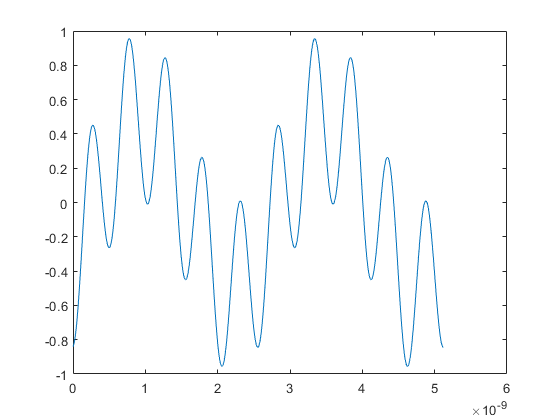


plot(t,S);

The frequencenies must be an integer multiplier of the fundamental frequency so that the resulting cosines are orthogonal. All the positive component of the cosines is counterbakanced by their negative's part. They are not correlated. 

If we take a square wave and modulates it trough a ODFM frequancy, the zeros of the sinc functions will be placed exactly on the other frequency carriers leading to no interference. 

ISI is tackle by sending 1 symbol through each channel for the period of time To that it will take a single fc to send all the symbols. 

e.g if we have 8 symbols to send, we will use 8 frequency carriers one for each symbol during To.

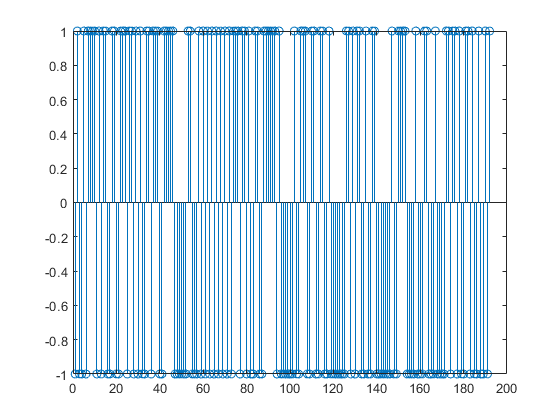

%let's demonstrate the statements above with BPSK
T  = 1/100e6; %symbol period
M = fs*T; %oversampling factor
n_symb = 24; %number of symbols of 8bits sended
sequence = [-1 1 1 -1 1 -1 1 -1];
rsequence =  randi(2,1,8*n_symb)-1;
n_f = 8;
seq_l =length(rsequence);
OS_rsequence = zeros(1,seq_l*M);
for i=1:length(rsequence)
    if not(rsequence(i))
            rsequence(i) = -1; %placing zero bits at -1
    end
    OS_rsequence(i:i+M-1) = rsequence(i);
end 

%Preordering the bits
figure(1);stem(rsequence);

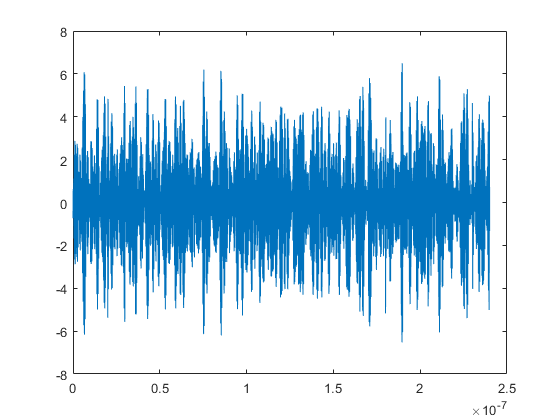

t = 0:t_res:n_symb*T-t_res;
%window = zeros(1,length(t)); window(round(0.5*T*seq_l/(t_res*n_f)):round((0.5+2*pi)*T*seq_l/(t_res*n_f)-2))=ones(1,round(2*pi*T*seq_l/(t_res*n_f)));

OFDM_signal = zeros(1,length(t));
for i = 1:n_f
    piou = rsequence(i:n_f:end);
    OS_piou = zeros(1,length(piou)*M);
    for j = 1:length(piou)
        OS_piou((j-1)*M +1:j*M-1)=piou(j);
    end
    OFDM_signal = OFDM_signal +  OS_piou.*cos(2*pi*t*(fc_central+(i-1)/T) + rand(1)*2*pi);%.*window; was for 1 symbol sended
end
plot(t,OFDM_signal)

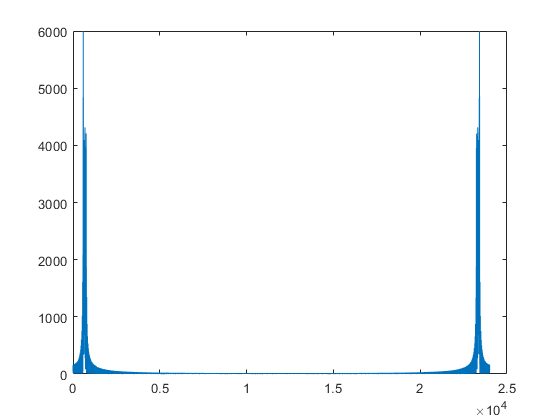

freq_component = fft(fftshift(OFDM_signal));
plot(abs(freq_component));

Now we will try to modulate the signal with the IFFT algorithm still for 8 carriers

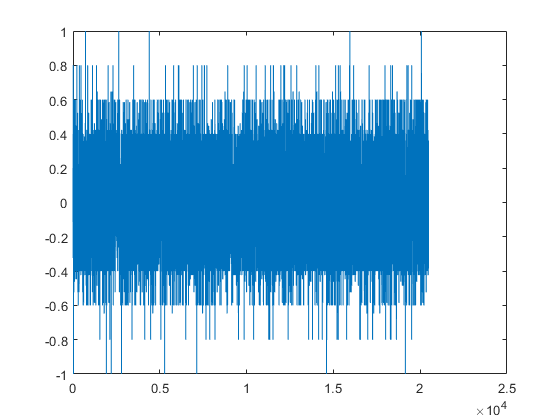

%BPSK symbols sended 
n_f = 2048;  %number of sub-carriers

nbits = 10*2048; %sending BPSK symbols
OFDM_symbol_size = 0;
x_bits = randi(2,1,nbits)-1; 
x = x_bits;
for i=1:nbits
    if not(x(i))
            x(i) = -1; %placing zero bits at -1 for BPSK
    end
end 

if mod(nbits,n_f) ==0 
    xr = reshape(x,nbits/n_f,n_f);
else 
    disp("error in serial parrallel")
end

X = ifft(xr,nbits/n_f,1);
Xr = reshape(X,1,nbits); %Parallel to serial
plot(real(Xr))

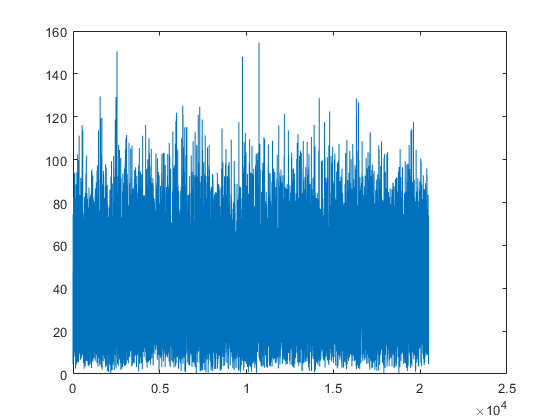

plot(abs(fftshift(fft(Xr)))) %can't say much about the plots yet


Xrbis = OFDM_modulation(x,n_f);
MSE_xr = sum(sqrt((abs(Xrbis-Xr)).^2))/nbits

MSE_xr = 0

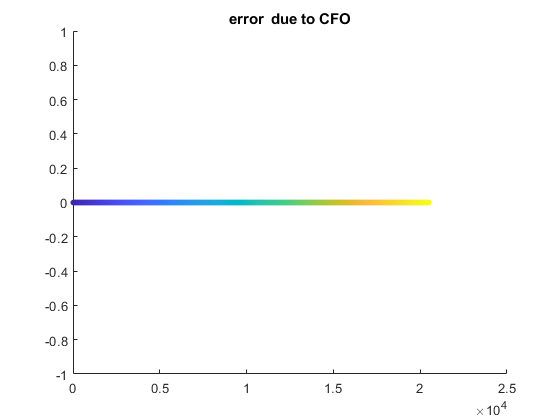


EbNo = 5; %ratio bit energy to noise energy
signal_energy = (trapz(abs(Xr).^2));     %energy of the signal
eb = (signal_energy) /(2* nbits);   %divided by 2 bcs it's a baseband signal
No = eb ./(10.^(EbNo/10));     % noise PSD
noise_power = 2*No; %psd 2 bp
noise = sqrt(noise_power/2).*(randn(1,nbits)+1i*randn(1,nbits));

Yn = Xr ; %Vanilla
%Yn  = add_STO(Yn,20); %adding STO 
%Yn = Yn +noise; %adding noise
%Yn  = add_CFO(Yn,20e4,nbits/n_f); %adds CFO


scatter(1:length(Yn),real(Yn-Xr),20 ,linspace(1,length(Yn),length(Yn)) ,'filled');title("error  due to CFO");

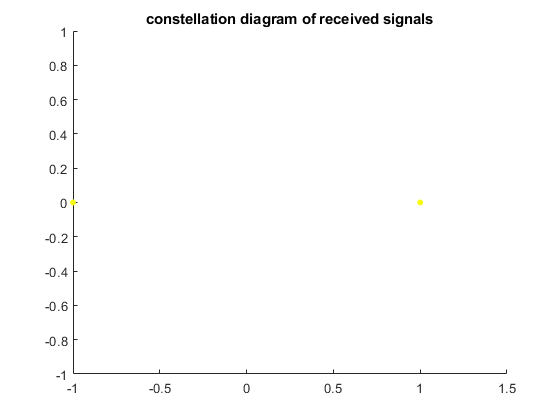

Y = reshape(Yn,nbits/n_f,n_f);
y = fft(Y,nbits/n_f);
yr = reshape(y,1,nbits);
scatter(real(yr),imag(yr),20,linspace(1,length(yr),length(yr)),'filled'); title("constellation diagram of received signals");


yr = demaping_BPSK_symbols(yr);


MSE = sum(sqrt((abs(x_bits-yr)).^2))/nbits

MSE = 0